**Synthetic Diagnostics: X-ray Production in a Uniform Plasma Cylinder**

This script models bremsstrahlung X-ray emission from a non-thermal electron population in a cylindrical plasma, using a 2D kappa velocity distribution representative of EBW-ECH conditions in MPEX.

**Key steps:**

- Define 2D kappa velocity distribution on a (v∥, v⊥) grid

- Initialize particles uniformly in the cylinder volume

- Compute electron density from particle count and volume

- Calculate spectral emissivity εₓ(ω) using:εₓ(ω) = nᵢ · ⟨σ(ω, v) · v · g_ff⟩ with σ(ω, v) from the Born approximation

- Integrate emissivity to obtain total X-ray power and photon rate

- Benchmark against Kunze’s analytic expression (Eq. 6.81)

**References**

- [1] H. A. Bethe & W. Heitler, *Proc. Roy. Soc. A* **146** (1934) 83.

- [2] H. J. Kunze, *Introduction to Plasma Spectroscopy*, Springer (2009), Ch. 6.

clear; clc; close all;

e    = 1.602e-19;       % Elementary charge [C]
hbar = 1.055e-34;       % Reduced Planck constant [J·s]
c    = 3e8;             % Speed of light [m/s]
me   = 9.109e-31;       % Electron mass [kg]
alpha= 1/137;           % Fine-structure constant
eps0 = 8.854e-12;       % Vacuum permittivity [F/m]
Z    = 1;               % Ion charge (hydrogen)
r_e  = e^2/(4*pi*eps0*me*c^2);  % Classical electron radius [m]
ER   = 13.605693 * e;  % Rydberg
kB   = 1.380649e-23;


**Define MPEX Cyl. Geometry:**

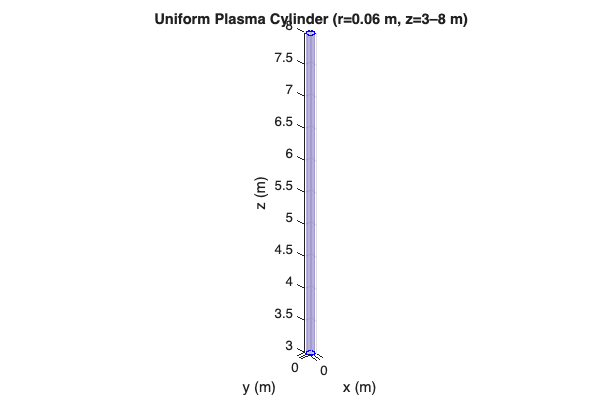

%% Cylinder Geometry
r_max   = 0.06;
z_start = 3;
z_end   = 8;
L       = z_end - z_start;
V_cyl   = pi * r_max^2 * L;

% Plot Cylinder Geometry
figure('Name','Cylinder Geometry','Position',[100 100 600 400]);
[Xc,Yc,Zc] = cylinder(r_max,100);
Zc = Zc * L + z_start;
surf(Xc,Yc,Zc,'FaceAlpha',0.2,'EdgeColor','none'); hold on;
theta = linspace(0,2*pi,200);
x_c = r_max*cos(theta); y_c = r_max*sin(theta);
plot3(x_c,y_c,z_start*ones(size(theta)),'b','LineWidth',1);
plot3(x_c,y_c,z_end*ones(size(theta)),'b','LineWidth',1);
xlabel('x (m)'); ylabel('y (m)'); zlabel('z (m)');
title('Uniform Plasma Cylinder (r=0.06 m, z=3–8 m)');
axis equal; grid on; view(3);

**Analytical non-thermal distribution**

%% 2D Kappa Velocity Distribution (Grid-Based)
kappa = 3;
T_e_k = 100 * e;
v_th  = sqrt(2*T_e_k/me);
Nv    = 200;
v_par  = linspace(-5*v_th,5*v_th,Nv);
v_perp = linspace(0,5*v_th,Nv);
[Vpar,Vperp] = meshgrid(v_par,v_perp);
V2 = Vpar.^2 + Vperp.^2;
f2D = (1 + V2./(kappa*v_th^2)).^(-(kappa+1));
dv_par  = v_par(2)-v_par(1);
dv_perp = v_perp(2)-v_perp(1);
norm2D  = sum(sum(f2D.*(2*pi.*Vperp))) * dv_par * dv_perp;
f2D     = f2D / norm2D;

% Plot 2D Distribution
figure('Name','2D Kappa Velocity Distribution','Position',[100 100 600 400]);
contourf(v_par/1e6, v_perp/1e6, f2D,50,'LineColor','none');
xlabel('v_{||} (10^6 m/s)'); ylabel('v_{\perp} (10^6 m/s)');
title(sprintf('2D Kappa Distribution (\kappa=%.1f)',kappa));

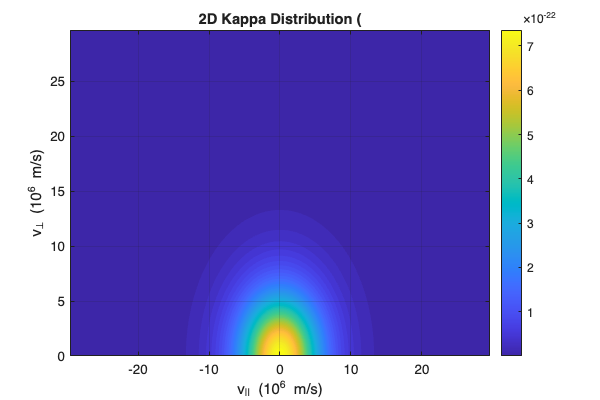

colorbar; grid on;

**Generate Particle based 1D-2V distrubution**

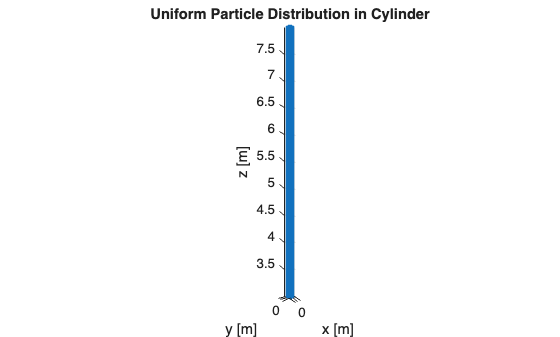


%% Particle Sampling in Cylinder Volume
N_particles = 1e6;    % Total particles
r_particles = r_max * sqrt(rand(N_particles,1));
theta_particles = 2*pi * rand(N_particles,1);
z_particles = z_start + L * rand(N_particles,1);
x_particles = r_particles .* cos(theta_particles);
y_particles = r_particles .* sin(theta_particles);

% Plot particle distribution
figure('Name','Particle Positions');
scatter3(x_particles, y_particles, z_particles, 1, '.'); axis equal;
xlabel('x [m]'); ylabel('y [m]'); zlabel('z [m]');
title('Uniform Particle Distribution in Cylinder'); grid on;

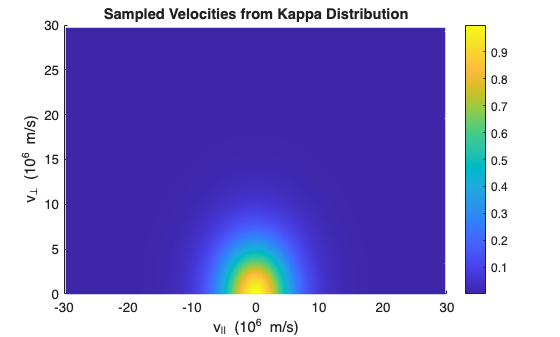


%% Assign Velocities Using Kappa Distribution
v_par_particles  = (2*rand(N_particles,1)-1) * 5*v_th;
v_perp_particles = rand(N_particles,1) * 5*v_th;
V2_particles = v_par_particles.^2 + v_perp_particles.^2;
f_kappa_particles = (1 + V2_particles./(kappa*v_th^2)).^(-(kappa+1));

% Plot velocity sampling
figure('Name','Sampled Velocities');
scatter(v_par_particles/1e6, v_perp_particles/1e6, 1, f_kappa_particles, '.');
xlabel('v_{||} (10^6 m/s)'); ylabel('v_{\perp} (10^6 m/s)');
title('Sampled Velocities from Kappa Distribution'); colorbar;


%% Calculate Density from Particle Count
ni = N_particles / V_cyl;

%% Derive Electron Temperature from 2D Distribution
mean_V2 = sum( sum( V2 .* f2D .* (2*pi.*Vperp) ) ) * dv_par * dv_perp;
Te_K    = me * mean_V2 / (3 * 1.380649e-23); % Convert to Kelvin
Te_eV   = Te_K * 1.380649e-23 / e;
fprintf('→ Derived T_e = %.2f eV (%.0f K)\n', Te_eV, Te_K);

→ Derived T_e = 184.59 eV (2141793 K)


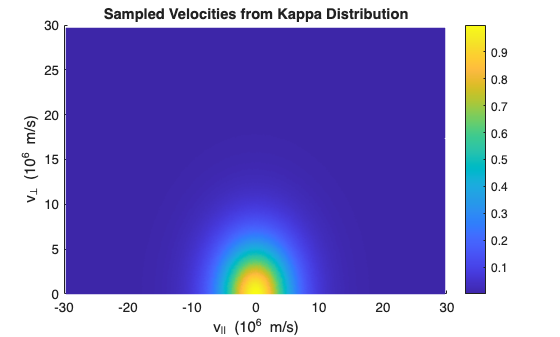


%% Assign Velocities from 2D Kappa Distribution
v_par_particles  = (2*rand(N_particles,1)-1) * 5*v_th;
v_perp_particles = rand(N_particles,1) * 5*v_th;
V2_particles = v_par_particles.^2 + v_perp_particles.^2;
f_kappa_particles = (1 + V2_particles./(kappa*v_th^2)).^(-(kappa+1));

% Plot sampled velocities
figure('Name','Sampled Velocities');
scatter(v_par_particles/1e6, v_perp_particles/1e6, 1, f_kappa_particles, '.');
xlabel('v_{||} (10^6 m/s)'); ylabel('v_{\perp} (10^6 m/s)');
title('Sampled Velocities from Kappa Distribution'); colorbar;

**Synthetic Diagnostics: X-ray Production in a Uniform Plasma Cylinder**

This simulation calculates bremsstrahlung X-ray emission from a 2D kappa-distributed electron population within a cylindrical plasma column (radius = 0.06 m, axial length = 5 m). It combines:

- Grid-based velocity diagnostics from a 2D kappa distribution

- Particle-based sampling to initialize plasma volume

- Numerical evaluation of bremsstrahlung cross-section and emissivity

- Comparison with analytical expressions from Kunze’s textbook

We compute both spectral emissivity \epsilon_X(\omega) and integrated power/photon emission using particle-based and analytic methods.

**Main References**

- [1] Bethe, H. A., & Heitler, W., *Proc. Roy. Soc. A*, **146** (1934), 83 — Born approximation to bremsstrahlung

- [2] Kunze, H. J., *Introduction to Plasma Spectroscopy*, Springer (2009) — Eq. 6.81 for analytic emissivity

**Born Approximation Cross-Section (Bethe & Heitler, 1934)**

This model computes the bremsstrahlung cross-section under the Born approximation:

σ(ω, v) = (16/3) · Z² · α · rₑ² · (mₑ·c² / ω) · ln[ 2E / (mₑ·c²) + 1 ]

Where:

- ω is the photon angular frequency

- Z is the ion charge state

- α is the fine-structure constant

- rₑ is the classical electron radius

- mₑ is the electron mass

- E = ½·mₑ·v² is the kinetic energy of the electron

This expression is evaluated numerically over a velocity distribution and averaged to compute spectral emissivity.

**Spectral Emissivity from Particle Average**

The volumetric emissivity is computed as:  ε_X(ω) = nᵢ · ⟨ σ(ω, v) · v · g_ff ⟩. This gives units of: [W·m⁻³·Hz⁻¹]

Here:

- nᵢ is ion density (computed from particle count and volume)

- g_ff is the Gaunt factor (quantum correction)

**Kunze’s Analytic Emissivity (Eq. 6.81)**

Kunze provides a semi-empirical analytic expression for the spectral emissivity (per unit wavelength):

ε_ff,λ(λ) = 4.108 × 10⁻⁴⁶ · n_i · n_e · Z² · sqrt(E_R / (k_B · T_e)) · λ⁻² · exp(–h·c / (λ·k_B·T_e)) · G_ff(λ, T_e)

Where:

- λ is the photon wavelength [m]

- E_R is the Rydberg energy (≈ 13.6 eV)

- G_ff is the Gaunt factor

- ε_ff,λ has units of [W·m⁻³·m⁻¹]

This is used as a benchmark to validate the numerically integrated emissivity.

**Free–Free Gaunt Factor Approximations**

The Gaunt factor g_{\rm ff} accounts for quantum corrections and depends on the Sommerfeld parameter \eta_Z and normalized photon energy \eta_\nu. Depending on the value of \eta_Z, different approximations apply:

- **Born limit** (η_Z ≪ 1): g_ff ≈ (√3 / π) · ln(1 / η_ν)

- **Classical limit** (η_Z ≫ 1): g_ff ≈ (√3 / π) · [ln(1 / (η_Z · η_ν)) – γ]

- **Rough full approximation** (Sutherland / Wikipedia): g_ff ≈ max[1, (√3 / π) · ln(1 / (η_ν · max(1, e^γ · η_Z)))]

Where:

- η_Z = \frac{Z e^2}{\hbar v} is the Sommerfeld parameter

- η_ν = \frac{\hbar \omega}{2 m_e v^2} is normalized photon energy

- γ ≈ 0.5772 is the Euler–Mascheroni constant

% omega_keV = linspace(0.1,20,200);
omega_keV = linspace(1, 15, 200);  % Focused on suprathermal contribution
omega_J   = omega_keV*1e3*e;
lambda_m  = (hbar .* c) ./ omega_J * 2*pi;  % Wavelength [m]

eps_omega = zeros(size(omega_J));
Vmag = sqrt(V2_particles);
gamma = 0.577215664901532;

for j = 1:numel(omega_J)
    omega = omega_J(j);
    
    eta_Z  = Z * e^2 ./ (hbar .* Vmag);
    eta_nu = hbar .* omega ./ (2 * me .* Vmag.^2);
    
    g_ff = (sqrt(3)/pi) .* log( 1 ./ (eta_nu .* max(1, exp(gamma) .* eta_Z)) );
    g_ff(g_ff < 1) = 1;

    E_part   = 0.5 * me .* V2_particles;
    log_term = log(2*E_part/(me*c^2) + 1);
    sigma    = (16/3) * Z^2 * alpha * r_e^2 .* (me*c^2./omega) .* log_term;

    % ✅ NEW — Includes photon energy hbar·omega
    emissivity = sigma .* Vmag .* g_ff .* (hbar * omega);  % [J/s per particle]
    eps_omega(j) = ni * mean(emissivity);                  % [W·m⁻³·Hz⁻¹]
end


### **Benchmark: Kunze Vs. Born**

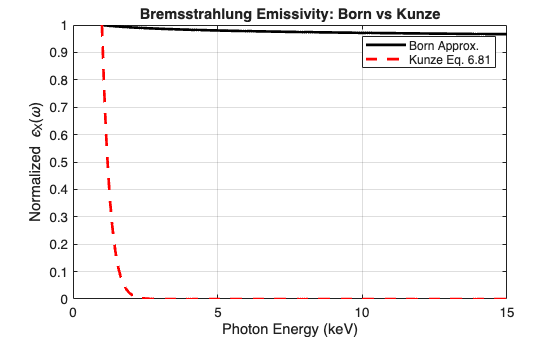

% Kunze Analytic
ne = ni;
g_ff_kunze = 1;
eps_kunze = 4.108e-46 * ni * ne * Z^2 * sqrt(ER / (kB * Te_K)) ...
            .* (1 ./ lambda_m.^2) .* exp(-hbar * c * 2 * pi ./ (lambda_m * kB * Te_K)) ...
            * g_ff_kunze;
eps_kunze = eps_kunze / max(eps_kunze);
eps_born = eps_omega / max(eps_omega);

% Plot Comparison
figure;
plot(omega_keV, eps_born, 'k-', 'LineWidth', 2); hold on;
plot(omega_keV, eps_kunze, 'r--', 'LineWidth', 2);
xlabel('Photon Energy (keV)');
ylabel('Normalized \epsilon_X(\omega)');
title('Bremsstrahlung Emissivity: Born vs Kunze');
legend('Born Approx.', 'Kunze Eq. 6.81'); grid on;

### X-ray calculations


%% Integrate to Get Power and Photon Rates
power_density  = trapz(omega_J, eps_omega .* omega_J);
phi_omega      = eps_omega ./ (hbar .* omega_J);
photon_density = trapz(omega_J, phi_omega);
total_power    = power_density * V_cyl;
total_photons  = photon_density * V_cyl;

%% Convert to eV Units
power_density_eV    = power_density / e;
total_power_eV_per_s= total_power   / e;

%% Display Final Results
fprintf('\n=== X-ray Production in Cylinder ===\n');


=== X-ray Production in Cylinder ===


fprintf('Cylinder volume: %.3f m^3\n', V_cyl);

Cylinder volume: 0.057 m^3


fprintf('Computed ni: %.3e m^-3\n', ni);

Computed ni: 1.768e+07 m^-3


fprintf('Power density: %.3e J/m^3/s (%.3e eV/m^3/s)\n', power_density, power_density_eV);

Power density: 1.058e-93 J/m^3/s (6.603e-75 eV/m^3/s)


fprintf('Total power:    %.3e J/s (%.3e eV/s)\n', total_power, total_power_eV_per_s);

Total power:    5.981e-95 J/s (3.734e-76 eV/s)


fprintf('Photon density: %.3e photons/m^3/s\n', photon_density);

Photon density: 9.552e-30 photons/m^3/s


fprintf('Total photons:  %.3e photons/s\n', total_photons);

Total photons:  5.401e-31 photons/s


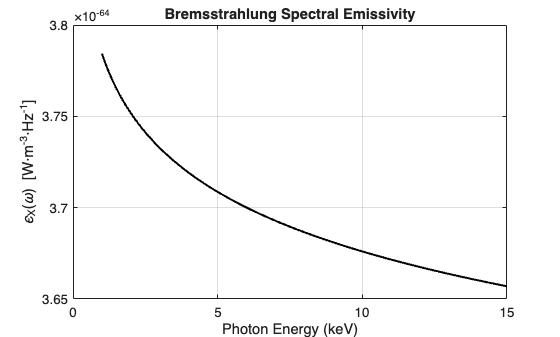


%% Plot Bremsstrahlung Emissivity Spectrum
figure('Name','Spectral Emissivity');
plot(omega_keV, eps_omega, 'k', 'LineWidth', 1.5);
xlabel('Photon Energy (keV)');
ylabel('\epsilon_X(\omega) [W·m^{-3}·Hz^{-1}]');
title('Bremsstrahlung Spectral Emissivity');
grid on;